clear all

load frame/1gTruth.mat
g1 = gTruth.DataSource;
tabletrain1  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);
clear gTruth

load frame/2gTruth.mat
g2 = gTruth.DataSource;
tabletrain2  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);
clear gTruth

load frame/3gTruth.mat
g3 = gTruth.DataSource;
tabletrain3  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);

tabletrain = [tabletrain1;tabletrain2;tabletrain3];

rng(0)
shuffledIndices = randperm(height(tabletrain));
idx = floor(0.7 * height(tabletrain));

trainingIdx = 1:idx;
trainingDataTbl = tabletrain(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = tabletrain(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = tabletrain(shuffledIndices(testIdx),:);

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:8));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,2:8));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,2:8));

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

numAnchors = 7;
anchorBoxes = estimateAnchorBoxes(trainingData,numAnchors)

anchorBoxes =     43    25
    30    16
    36    21
    20    12
    61    37
    86    52
    53    29


featureExtractionNetwork = resnet50;
featureLayer = 'activation_40_relu';
numClasses = 7;
%1

inputSize = [224 224 3];
lgraph = fasterRCNNLayers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

options = trainingOptions('sgdm',...
    'MaxEpochs',2,...
    'MiniBatchSize',1,...
    'InitialLearnRate',1e-3,...
    'ExecutionEnvironment','gpu',...
    "Plots","training-progress",...
    "ValidationData",validationData);

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* Batuhan
* Berkant
* Damla
* Enes
* Erdem
* Muhammed
* Omer

Initializing input data normalization.
|==========================================================================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Validation  |  Validation  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|======================================================================================================================================================================================

|       1 |           1 |       00:05:29 |       3.6281 |        0.00% |              |           35.00% |             1.15 |       1.9338 |       92.14% |         0.19 |          0.0010 |


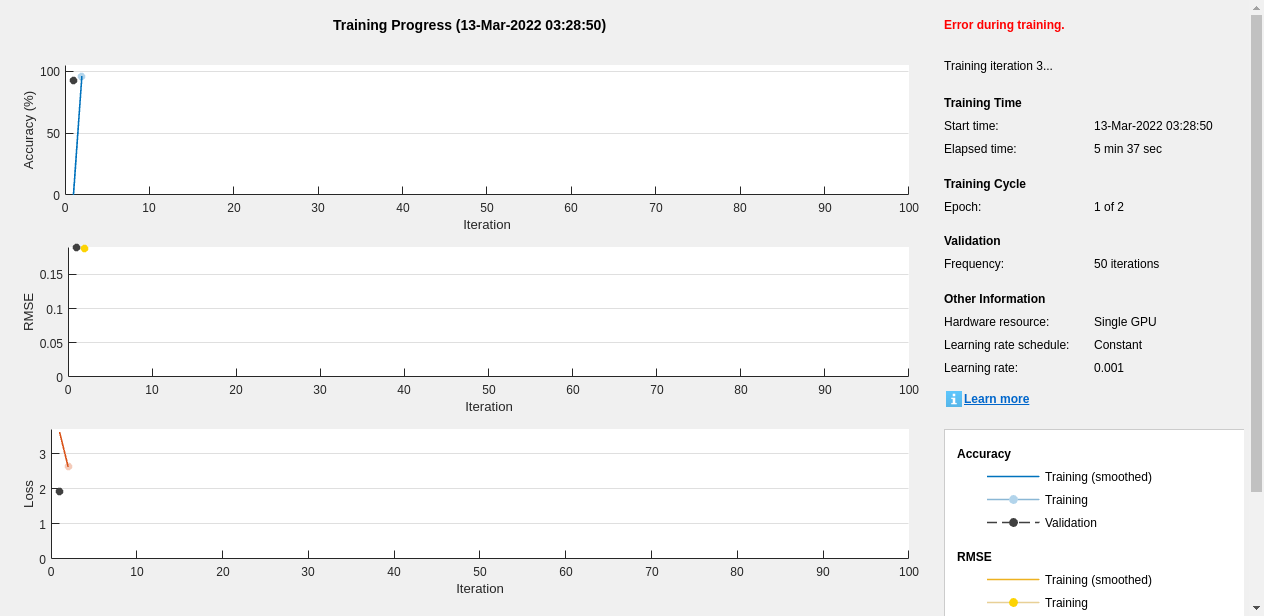

Error using  + 
Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

Error in nnet.internal.cnn.DAGNetwork>iIncrementActivationsInBuffer (line 1524)
        activationsBuffer{bufferIndices} = activationsBuffer{bufferIndices} + activations;

Error in 

[detector, info] = trainFasterRCNNObjectDetector(trainingData,lgraph,options);

detectionResults = detect(detector,testData,'MinibatchSize',2);   

[ap, recall, precision] = evaluateDetectionPrecision(detectionResults,testData,0.3);

[am, fppi, missRate] = evaluateDetectionMissRate(detectionResults, testData);

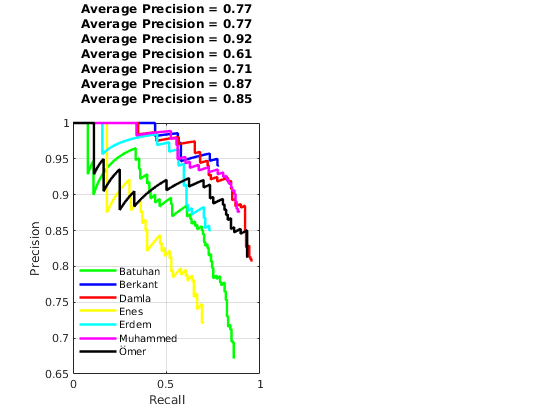

subplot(1,2,1);
plot(recall{1,1},precision{1,1},'g-','LineWidth',2, "DisplayName","Batuhan");
hold on;
plot(recall{2,1},precision{2,1},'b-','LineWidth',2, "DisplayName",'Berkant');
hold on;
plot(recall{3,1},precision{3,1},'r-','LineWidth',2, "DisplayName",'Damla');
hold on;
plot(recall{4,1},precision{4,1},'y-','LineWidth',2, "DisplayName",'Enes');
hold on;
plot(recall{5,1},precision{5,1},'c-','LineWidth',2, "DisplayName",'Erdem');
hold on;
plot(recall{6,1},precision{6,1},'m-','LineWidth',2, "DisplayName",'Muhammed');
hold on;
plot(recall{7,1},precision{7,1},'k-','LineWidth',2, "DisplayName",'Ömer');
hold off;

xlabel('Recall');
ylabel('Precision');
title(sprintf('Average Precision = %.2f\n', ap))
legend('Location', 'best');
legend('boxoff')
grid on

## Performans Tablo

%figure
%plot(recall,precision)
%xlabel('Recall')
%ylabel('Precision')
%grid on
%title(sprintf('Average Precision = %.2f', ap))

## Tekli Performans Kontrol

%img = imread('C:\Users\Batu\Desktop\dji_tello_face_detect_aiis\data_collect\data\resized_1-20220308T192705Z-001\resized_1\01138.jpg');
%[bbox, score, label] = detect(detector, img)
%detectedI = insertObjectAnnotation(img,'Rectangle',bbox,cellstr(label));
%figure
%imshow(detectedI)

## Etiket Sayma


%%A = table2array(trainingDataTbl(:,5));
%matcell = cell2mat(A);
%size(matcell)
